# Wildtype data

histoLat =     64
    62
    69
    56
    21
    50
    43
    51
    36
    66


histoLat =     60
    56
    94
    72
    33
    50
    98
    39
    24
    69


histoLat =     47
   102
    34
    38
    97
    45
    30
    33
    65
   108


histoLat =     46
    40
   103
    34
   101
    36
    80
    60
    82
    83


histoLat =     50
    24
    52
    96
    61
    41
    39
    43
    33
    95


histoLat =     76
    93
    64
    18
    34
    77
    50
    77
    40
    44


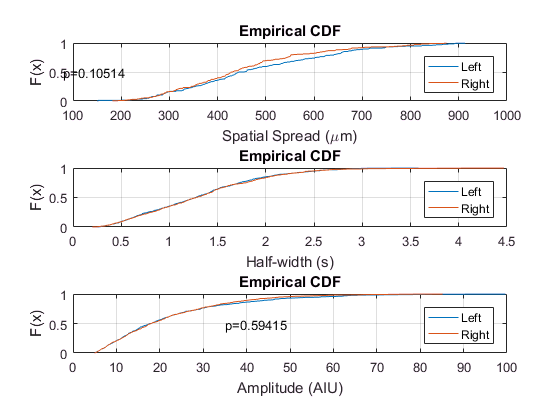

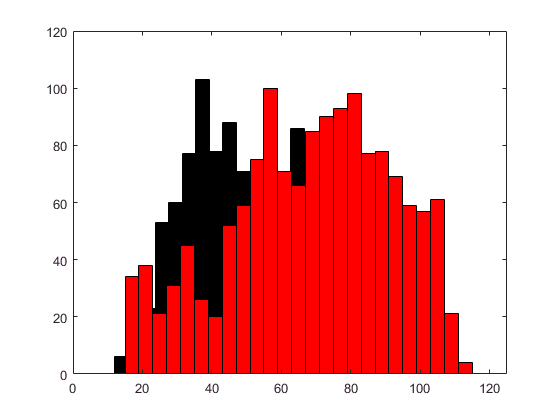

load('M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\GroupData_paths.mat');
paths = groupData;
%[WTgroupHistoL,WTgroupHistoR,WTtotalEvents,WTindividualStats] = analGroupData(paths,1);
[WTgroupHistoL,WTgroupHistoR,WTtotalEvents,WTindividualStats] = analGroupDataLR(paths,1);

## KO Data

load('M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\groupDataKO.mat');
paths = groupDataKO;
[KOgroupHistoL,KOgroupHistoR,KOtotalEvents,KOindividualStats] = analGroupData(paths,1);


## Compare WT KO

compareFig('P2ry1+/+', WTtotalEvents, WTgroupHistoL, WTgroupHistoR, 'P2ry1–/–', KOtotalEvents, KOgroupHistoL, KOgroupHistoR);
compareStats('P2ry1+/+', WTindividualStats, 'P2ry1–/–', KOindividualStats,1);

## Vglut3 data

load('M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\GroupData_paths.mat');
paths = VG3groupData(:,3);

VG3groupHistoL = [];
VG3groupHistoR = [];
VG3groupAmpL = [];
VG3groupAmpR = [];
VG3totalEvents = [];
VG3individualStats = [];


for i=1:size(paths)
    load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
    %[smLIC, peaksBinaryL] = getPeaks(LICmov,0);
    %[smRIC, peaksBinaryR] = getPeaks(RICmov,1);
    
    
    [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
    VG3individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmean(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100];
    
    peaksL = peakStat{1};
    peaksR = peakStat{2};
    VG3groupHistoL = [VG3groupHistoL; peaksL(:,2)];
    VG3groupHistoR = [VG3groupHistoR; peaksR(:,2)];
    VG3groupAmpL = [VG3groupAmpL; i*ones(size(peaksL,1),1), peaksL];
    VG3groupAmpR = [VG3groupAmpR; i*ones(size(peaksR,1),1), peaksR];
    VG3totalEvents = [VG3totalEvents; eventStats];
    
   
%     tempR = stats;
%     statsR = [statsR; stats];
%     
%     meanHW = [meanHW; mean([tempL.halfwidths;tempR.halfwidths])];
%     totalEvents = [totalEvents; size(tempL.eventLabels,1)];
end

## Salicylate data

load('M:\Bergles Lab Data\Projects\In vivo imaging\Salicylate\GroupData_paths.mat');
paths = SalgroupData(:,3);

SalgroupHistoL = [];
SalgroupHistoR = [];
SalgroupAmpL = [];
SalgroupAmpR = [];
SaltotalEvents = [];
SalindividualStats = [];


for i=1:size(paths)
    load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
    %[smLIC, peaksBinaryL] = getPeaks(LICmov,0);
    %[smRIC, peaksBinaryR] = getPeaks(RICmov,1);
    
    
    [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    %plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
    SalindividualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx)];
    
    peaksL = peakStat{1};
    peaksR = peakStat{2};
    SalgroupHistoL = [SalgroupHistoL; peaksL(:,2)];
    SalgroupHistoR = [SalgroupHistoR; peaksR(:,2)];
    SalgroupAmpL = [SalgroupAmpL; i*ones(size(peaksL,1),1), peaksL];
    SalgroupAmpR = [SalgroupAmpR; i*ones(size(peaksR,1),1), peaksR];
    SaltotalEvents = [SaltotalEvents; eventStats];
    
%     tempR = stats;
%     statsR = [statsR; stats];
%     
%     meanHW = [meanHW; mean([tempL.halfwidths;tempR.halfwidths])];
%     totalEvents = [totalEvents; size(tempL.eventLabels,1)];
end


%%a9 data
% load('M:\Bergles Lab Data\Projects\In vivo imaging\a9 KO\GroupData_paths.mat');
%  paths = a9groupData(:,3);
% 
% a9groupHistoL = [];
% a9groupHistoR = [];
% a9groupAmpL = [];
% a9groupAmpR = [];
% a9totalEvents = [];
% 
% 
% for i=1:size(paths)
%     load(paths{i});
%     [smLIC, peaksBinaryL] = getPeaks(LICmov,0);
%     [smRIC, peaksBinaryR] = getPeaks(RICmov,1);
%     
%     
%     [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
%     %plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
%     
%     peaksL = peakStat{1};
%     peaksR = peakStat{2};
%     a9groupHistoL = [a9groupHistoL; peaksL(:,2)];
%     a9groupHistoR = [a9groupHistoR; peaksR(:,2)];
%     a9groupAmpL = [a9groupAmpL; i*ones(size(peaksL,1),1), peaksL];
%     a9groupAmpR = [a9groupAmpR; i*ones(size(peaksR,1),1), peaksR];
%     a9totalEvents = [a9totalEvents; eventStats];
%     
% %     tempR = stats;
% %     statsR = [statsR; stats];
% %     
% %     meanHW = [meanHW; mean([tempL.halfwidths;tempR.halfwidths])];
% %     totalEvents = [totalEvents; size(tempL.eventLabels,1)];
% end
% 
% close all;

## NBQX Data

## Bilat Mannitol

paths = {'564' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-594-Snap25GC6s_mannitol_sham_bilat_PCA\ICmovs_peaks.mat';
         '602' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-602_Snap25GC6s_mannitol_sham_bilat_PCA\ICmovs_peaks.mat';
         '620' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-620_Snap25GC6s_mannitolsham_bilat_PCA\ICmovs_peaks.mat';
         %'622' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-622_Snap25GC6s_mannitolsham_bilat_PCA\ICmovs_peaks.mat'
         '625' 'Mannitol Sham' 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-625_Snap25GC6s_mannitolsham_bilat_2_355_PCA\ICmovs_peaks.mat'
         };
     
[bShamgroupHistoL,bShamgroupHistoR,bShamtotalEvents,bShamindividualStats] = analGroupData(paths,1);

## Bilat MRS2500

paths = {'592' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-592_P7_Snap25GC6s_MRS2500double_PCA\ICmovs_peaks.mat';
         '601' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-601_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat';
         '619' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-619_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat';
          '622' 'bilat MRS' 'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-623_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat';
           '626' 'bilat MRS' 'C:\Users\Bergles Lab\Desktop\DUP_Experiment-626_Snap25GC6s_MRS2500_bilat_PCA\ICmovs_peaks.mat'
         };
     
[MRSgroupHistoL,MRSgroupHistoR,MRStotalEvents,MRSindividualStats] = analGroupData(paths,1);

## Compare Bilat Mannitol and MRS2500

compareFig('Sham', bShamtotalEvents, bShamgroupHistoL, bShamgroupHistoR, 'MRS2500', MRStotalEvents, MRSgroupHistoL, MRSgroupHistoR);
compareStats('Sham', bShamindividualStats, 'MRS2500', MRSindividualStats'''''''''',1);

histoLat =     66
    18
    20
    55
   104
    97
    31
    41
    27
    29


histoLat =     42
    53
    79
    26
    72
    30
    76
    83
    30
    27


histoLat =     94
    35
    54
    53
    92
    67
    76
    92
    24
    34


histoLat =     47
    73
    38
    81
    86
    19
    46
    68
    39
    33


h =    1


p = 0.0403

h =    0


p = 0.4472

h =    1


p = 0.0052

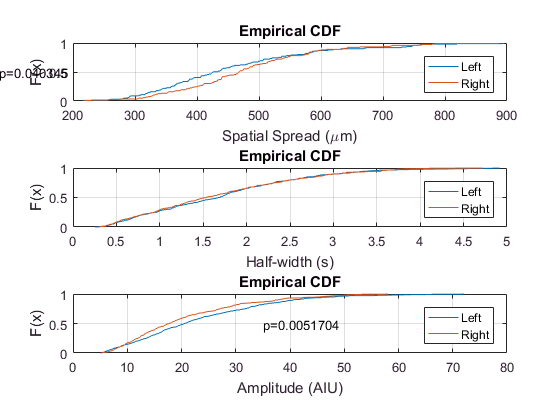

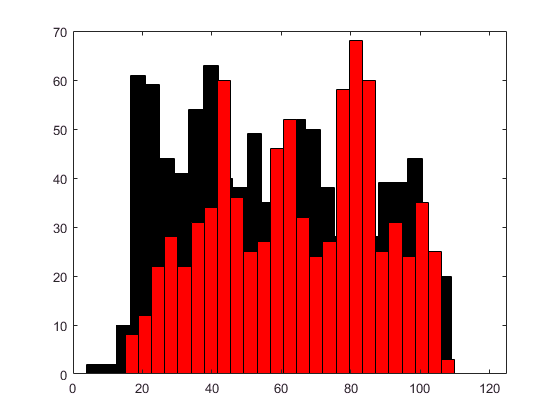

%%Testing
  
paths = {'652' 'ctx_ablation' 'C:\Users\Bergles Lab\Desktop\pExperiment-652_P7_Snap25GC6s_A1_decerebration_celebration_PCA\ICmovs_peaks.mat';
         '660' 'ctx_abaltion' 'C:\Users\Bergles Lab\Desktop\pExperiment-660_PCA\ICmovs_peaks.mat';
         '689' 'ctx_abaltion' 'C:\Users\Bergles Lab\Desktop\pExperiment-689_PCA\ICmovs_peaks.mat';
         '690' 'ctx_abaltion' 'C:\Users\Bergles Lab\Desktop\pExperiment-690_PCA\ICmovs_peaks.mat'};
         %'693' 'ctx_abaltion' 'C:\Users\Bergles Lab\Desktop\pExperiment-693_PCA\ICmovs_peaks.mat'};
[ctxgroupHistoL,ctxgroupHistoR,ctxtotalEvents,ctxindividualStats] = analGroupDataLR(paths,1);

## Plot

function compareFig(cond1, totalEvents, lHisto, rHisto, cond2, totalEvents2, lHisto2, rHisto2)
    cutoff =0;
    figure;

    subplot(3,1,1);
    cdfplot(totalEvents.hwx(totalEvents.domAmp > cutoff)*7.45);
    hold on;
    cdfplot(totalEvents2.hwx(totalEvents2.domAmp > cutoff)*7.45);
    xlabel('Spatial Spread (\mum)');
    legend(cond1,cond2);
    
    subplot(3,1,2);
    cdfplot(totalEvents.hwt(totalEvents.domAmp > cutoff)/10);
    hold on;
    cdfplot(totalEvents2.hwt(totalEvents2.domAmp > cutoff)/10);
    xlabel('Half-width (s)');
    legend(cond1,cond2);
    
    subplot(3,1,3);
    cdfplot(totalEvents.domAmp);
    hold on;
    cdfplot(totalEvents2.domAmp);
    xlabel('Amplitude (AIU)');
    legend(cond1,cond2);
    
    %%more plot
    figure;
    histogram([lHisto; abs(rHisto-125)],25,'faceColor','black','edgeColor','black','faceAlpha',1)
    xlim([0,125]);
    hold on;
    histogram([lHisto2; abs(rHisto2-125)],25,'faceColor','red','edgeColor','black','faceAlpha',1)
    
    figure;
    ksdensity([lHisto; abs(rHisto-125)]);
    hold on;
    yyaxis right;
    ksdensity([lHisto2; abs(rHisto2-125)]);
end

function compareFigLR(lEvents, rEvents,lHisto, rHisto)
    figure;
    cond1 = 'Left';
    cond2 = 'Right';
    
    subplot(3,1,1);
    cdfplot(lEvents(:,2)*7.45);
    hold on;
    cdfplot(rEvents(:,2)*7.45);
    xlabel('Spatial Spread (\mum)');
    legend(cond1,cond2);
    [h,p]=kstest2(lEvents(:,2),rEvents(:,2))
    text(80,0.5, strcat('p=',num2str(p)))
    
    subplot(3,1,2);
    cdfplot(lEvents(:,1)/10);
    hold on;
    cdfplot(rEvents(:,1)/10);
    xlabel('Half-width (s)');
    legend(cond1,cond2);
    [h,p]=kstest2(lEvents(:,1),rEvents(:,1))
    text(30,0.5,  strcat('p=',num2str(p)))
    
    subplot(3,1,3);
    cdfplot(lEvents(:,3));
    hold on;
    cdfplot(rEvents(:,3));
    xlabel('Amplitude (AIU)');
    legend(cond1,cond2);
    [h,p]=kstest2(lEvents(:,3),rEvents(:,3))
    text(35,0.5,  strcat('p=',num2str(p)))
    
    %%more plot
    figure;
    histogram([lHisto],25,'faceColor','black','edgeColor','black','faceAlpha',1)
    xlim([0,125]);
    hold on;
    histogram([rHisto],25,'faceColor','red','edgeColor','black','faceAlpha',1)
    
end

function compareStats(cond1, indStats, cond2, indStats2, plotFlag)
    m = size(indStats,1);
    m2 = size(indStats2,1);
    
    if(plotFlag)
        figure;
        %frequency
        subplot(1,3,1);
            scatter(ones(m,1), indStats(:,1)/10)
            hold on;
            scatter(2*ones(m2,1), indStats2(:,1)/10)
            ylim([0,25]);
            xlim([0 3]);
            xticklabels({'',cond1,cond2,''});
            ylabel('Frequency (events/min)');
        %amplitude
        subplot(1,3,2);
            scatter(ones(m,1), indStats(:,2))
            hold on;
            scatter(2*ones(m2,1), indStats2(:,2))
            ylim([0,25]);
            xlim([0 3]);
            xticklabels({'',cond1,cond2,''});
            ylabel('Amplitude (AIU)');
        subplot(1,3,3);
            scatter(ones(m,1), indStats(:,4)*7.45)
            hold on;
            scatter(2*ones(m2,1), indStats2(:,4)*7.45)
            ylim([0,800]);
            xlim([0 3]);
            xticklabels({'',cond1,cond2,''});
            ylabel('Spatial Spread (\mum)');
        
    end
end


## Group Data

function [groupHistoL,groupHistoR,totalEvents,individualStats] = analGroupData(paths,plotFlag)
    paths = paths(:,3);
    groupHistoL = [];
    groupHistoR = [];
    totalEvents = [];
    individualStats = [];

    for i=1:size(paths)
        load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
%         load(paths{i});
%         [smLIC, peaksBinaryL] = getPeaks(LICmov,0,0.25);
%         [smRIC, peaksBinaryR] = getPeaks(RICmov,1,0.25);
%         savefile = '\ICmovs_peaks.mat';
%         [path, fn, ext ] = fileparts(paths{i});
%         save([path savefile],'LICmov','RICmov','smLIC','smRIC','peaksBinaryR','peaksBinaryL');
        %size(peaksBinaryR)
        %size(peaksBinaryL)
        
        [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
       
        %eventStat = table(eventLabel, eventClassification, leftOrRightDom, numPeaks, domAmp, maxLAmp, maxRAmp,xloc, tloc, hwt, hwx);
        peaksL = peakStat{1};
        peaksR = peakStat{2};
        groupHistoL = [groupHistoL; peaksL(:,2)];
        groupHistoR = [groupHistoR; peaksR(:,2)];
        histoLat = [peaksL(:,2); abs(peaksR(:,2)-125)]
        histoLat = histoLat(histoLat > 50);
        histoLat = histoLat(histoLat < 100);
        totalEvents = [totalEvents; eventStats];
        individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100 size(histoLat,1)];
        
        
        if(plotFlag)
          plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
        end
    
    end
    
end


## Group Data

function [groupHistoL,groupHistoR,totalEvents,individualStats] = analGroupDataLR(paths,plotFlag)
    paths = paths(:,3);
    groupHistoL = [];
    groupHistoR = [];
    totalEvents = [];
    individualStats = [];
    hwtL = [];
    hwtR = [];
    hwxL = [];
    hwxR = [];
    ampL = [];
    ampR = [];
    
    for i=1:size(paths)
        load(paths{i},'-regexp','^(?!LICmov|RICmov)...');
%         load(paths{i});
%         [smLIC, peaksBinaryL] = getPeaks(LICmov,0,0.25);
%         [smRIC, peaksBinaryR] = getPeaks(RICmov,1,0.25);
%         savefile = '\ICmovs_peaks.mat';
%         [path, fn, ext ] = fileparts(paths{i});
%         save([path savefile],'LICmov','RICmov','smLIC','smRIC','peaksBinaryR','peaksBinaryL');
        %size(peaksBinaryR)
        %size(peaksBinaryL)
        
        [peakStat, eventStats] = peakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
       
        %eventStat = table(eventLabel, eventClassification, leftOrRightDom, numPeaks, domAmp, maxLAmp, maxRAmp,xloc, tloc, hwt, hwx);
        peaksL = peakStat{1};
        peaksR = peakStat{2};
        groupHistoL = [groupHistoL; peaksL(:,2)];
        groupHistoR = [groupHistoR; peaksR(:,2)];
        histoLat = [peaksL(:,2); abs(peaksR(:,2)-125)]
        histoLat = histoLat(histoLat > 50);
        histoLat = histoLat(histoLat < 100);
        totalEvents = [totalEvents; eventStats];
        %individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100 size(histoLat,1)];
        
        %left right compariason
        hwtLdist = eventStats.hwt(strcmp('Left', cellstr(eventStats.leftOrRightDom)));
        hwtRdist = eventStats.hwt(strcmp('Right', cellstr(eventStats.leftOrRightDom)));
        hwtL = [hwtL; hwtLdist];
        hwtR = [hwtR; hwtRdist];
        hwtLavg = median(hwtLdist);
        hwtRavg = median(hwtRdist);
        
        hwxLdist = eventStats.hwx(strcmp('Left', cellstr(eventStats.leftOrRightDom)));
        hwxRdist = eventStats.hwx(strcmp('Right', cellstr(eventStats.leftOrRightDom)));
        hwxL = [hwxL; hwxLdist];
        hwxR = [hwxR; hwxRdist];
        hwxLavg = nanmedian(hwxLdist);
        hwxRavg = nanmedian(hwxRdist);
        
        ampLdist = eventStats.domAmp(strcmp('Left', cellstr(eventStats.leftOrRightDom)));
        ampRdist = eventStats.domAmp(strcmp('Right', cellstr(eventStats.leftOrRightDom)));
        ampL = [ampL; ampLdist];
        ampR = [ampR; ampRdist];
        ampLavg = median(ampLdist);
        ampRavg = median(ampRdist);
        individualStats(i,:) = [max(eventStats.eventLabel) median(eventStats.domAmp) median(eventStats.hwt) nanmedian(eventStats.hwx) size((find(eventStats.numPeaks > 1)),1)/max(eventStats.eventLabel)*100 size(histoLat,1)...
            hwtLavg hwtRavg hwxLavg hwxRavg ampLavg ampRavg...
            kstest2(hwtLdist,hwtRdist) kstest2(hwxLdist,hwxRdist) kstest2(ampLdist,ampRdist)];
        
    
    end
    
    if(plotFlag)
          %plotTimeSeries(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
          compareFigLR([hwtL hwxL ampL], [hwtR hwxR ampR],groupHistoL, groupHistoR);
        end
    
end
